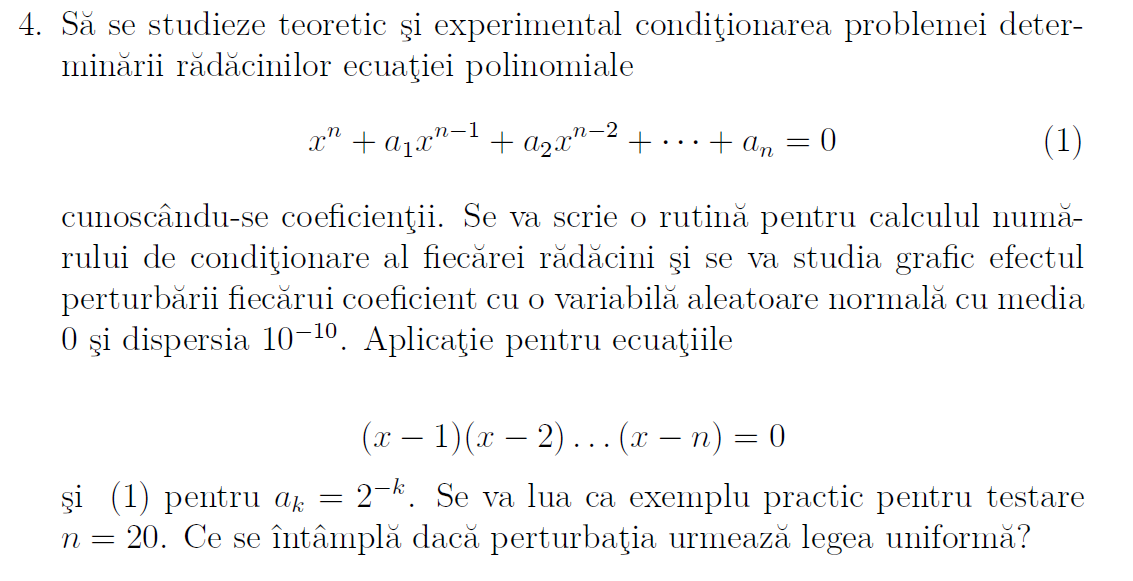

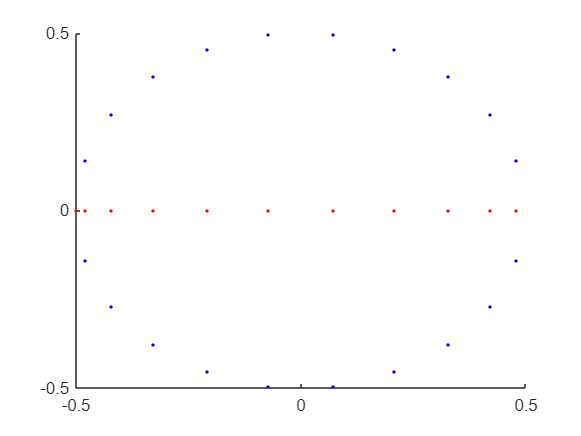

nr_de_conditionare_pt_radacini = 	1.0e+10 *

    0.3385    0.3606    0.2133    0.1361    0.4154    0.1155    0.1180    0.9788    0.7407    0.1124    0.1042    0.0000    0.1591    0.0977    0.6657    0.1161    0.3497    0.4033    0.9905    0.1400    0.1095    0.1349    0.7283    0.1279    0.0000    0.2980    0.1023    0.2622    0.1088    0.0000    1.0847    0.1474    0.5934    0.0000    0.2529    0.1066    0.0000    0.2183    0.8974    0.3185    0.2509    0.0972    0.1226    0.8260    0.1827    0.3629    0.1654    0.1581    0.2760    0.1308


coef = zeros(1, 21);
coef(1, 1) = 1;
for i=21:-1:1
    coef(1, i + 1) = 2^(-i);
end


%my_poly(poly(1:20))
my_poly(coef)

function my_poly(coeficienti)
clf; hold on;
n = length(coeficienti) - 1;
nr_de_conditionare_pt_radacini = zeros(size(n));
for i=1:100
  perturbari = randn(1,n+1) * 1e-10;
  r = roots(coeficienti);
  coeficienti_perturbati = coeficienti + perturbari;
  r_perturbate=roots(coeficienti_perturbati);
  nr_de_conditionare_pt_radacini(i) = norm(r - r_perturbate) / norm(perturbari);
  plot(real(r_perturbate),imag(r_perturbate),'b.');
 end
 plot(r,zeros(1,n),'r.');
 nr_de_conditionare_pt_radacini
end